# 案例：PLS 回归

clear;clc;
% x = [4 9 6 7 7 8 3 2;6 15 10 15 17 22 9 4;8 21 14 23 27 36 15 6;
% 10 21 14 13 11 10 3 4; 12 27 18 21 21 24 9 6; 14 33 22 29 31 38 15 8;
% 16 33 22 19 15 12 3 6; 18 39 26 27 25 26 9 8;20 45 30 35 35 40 15 10];
% y = [1 1;3 1;5 1;1 3;3 3;5 3;1 5;3 5;5 5];
pz = load('zdj10_1.txt');
x = pz(:, 1:10);
y = pz(:, 1);
[sol, yhat] = PLSRegress(x, y);

提出的成分个数r = 2


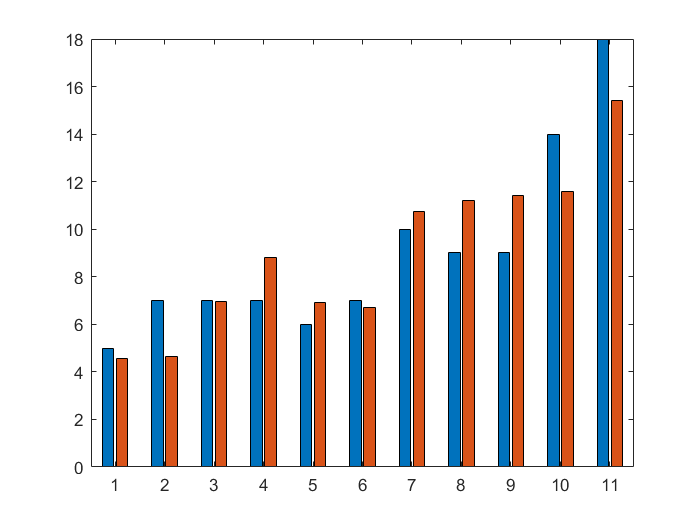

bar([y(:, 1), yhat(:, 1)]);

function [sol, yhat] = PLSRegress(x, y)
[rX, n] = size(x);           % 自变量个数
[rY, m] = size(y);           % 因变量个数
assert(rX == rY, 'x和y的横向维度不一致！');
%%% 标准化数据
xmean = mean(x);    % 每一列均值
xstd = std(x);      % 每一列标准差
ymean = mean(y);    % 每一列均值
ystd = std(y);      % 每一列标准差
e0 = (x - xmean(ones(rX, 1), :)) ./ xstd(ones(rX, 1), :);
f0 = (y - ymean(ones(rY, 1), :)) ./ ystd(ones(rY, 1), :);
%%% 迭代计算
chg = eye(n);          % w到w*变换矩阵的初始化
w = zeros(n, n);
w_star = zeros(n, n);
t = zeros(rX, n);
ss = zeros(1, n);
press_i = zeros(1, rX);
press = zeros(1, n);
Q_h2 = zeros(1, n);
for i = 1:n
    % 以下计算w，w*和t的得分向量
    % 提取最大特征值和对应的特征向量
    w(:, i) = MaxEig(f0'*e0);
    w_star(:, i) = chg * w(:, i);             % 计算w*的取值
    t(:, i) = e0*w(:, i);                     % 计算成分ti的得分
    alpha = e0'*t(:, i)/(t(:, i)'*t(:, i));   % 计算alpha_i
    chg = chg*(eye(n) - w(:, i)*alpha');      % 计算w到w*的变换矩阵
    e = e0 - t(:, i)*alpha';                  % 计算残差
    e0 = e;
    % 以下计算ss(i)的值
    beta = SolveEquations([t(:, 1:i), ones(rX, 1)], f0); % 求回归方程的系数
%     beta = [t(:, 1:i), ones(rX, 1)] \ f0;     % 求回归方程的系数
    beta(end, :) = [];                        % 删除回归分析的常数项
    cancha = f0 - t(:, 1:i)*beta;             % 残差
    ss(i) = norm(cancha)^2;                   % 误差平方和
    % 以下计算press(i)
    for j = 1:rX
        t1 = t(:, 1:i);
        f1 = f0;
        she_t = t1(j, :);               % 保存舍去的第j个样本点
        she_f = f1(j, :);
        t1(j, :) = [];                  % 删除第j个观测值
        f1(j, :) = [];
        beta1 = SolveEquations([t1, ones(rX - 1, 1)], f1); % 求回归方程的系数
%         beta1 = [t1, ones(rX - 1, 1)]\f1;  % 求回归分析的系数
        beta1(end, :) = [];                % 删除回归分析的常数项
        cancha = she_f - she_t * beta1;      % 残差
        press_i(j) = norm(cancha)^2;             
    end
    press(i) = sum(press_i);
    if i > 1
        Q_h2(i) = 1 - press(i) / ss(i - 1);
    else
        Q_h2(i) = 1;
    end
    if Q_h2(i) < 0.0975
        fprintf('提出的成分个数r = %d\n', i);
        r = i;
        break;
    end
end
beta_z = SolveEquations([t(:, 1:r), ones(rX, 1)], f0);  % 求Y关于t的回归系数
% beta_z = [t(:, 1:r), ones(rX, 1)]\f0;   % 求Y关于t的回归系数
beta_z(end, :) = [];                      % 删除常数项
xishu = w_star(:, 1:r) * beta_z;          % 求Y关于标准数据X的回归系数，每一列是一个回归方程
% 计算原始数据的回归方程的常数项
ch0 = zeros(1, m);
for i = 1:m
    ch0(i) = ymean(i) - xmean ./ xstd * ystd(i) * xishu(:, i);    
end
% 计算原始数据的回归方程的系数，每一列是一个回归方程
xish = zeros(n, m);
for i = 1:m
    xish(:, i) = xishu(:, i) ./ xstd' * ystd(i);    
end
sol = [ch0; xish];    
yhat = [ones(size(x, 1), 1), x] * sol;
end


function x = SolveEquations(A, y)
[m, n] = size(A);
[u, s, v] = svd(A);
s(s < 1e-10) = 0;
for i = 1 : min(m, n)
    if s(i, i) > 0
        s(i, i) = 1 / s(i, i);
    end
end
x = v * s' * u' * y;
end


function [Eigenvalue, Eigenvector] = MaxEig(A, tol)
%{
函数功能：计算由实数矩阵A构成的对称矩阵A'*A的最大特征值和对应的特征向量
输入：
  A：实数矩阵；
  tol：收敛精度，默认1e-6；
输出：
  Eigenvalue：最大特征值；
  Eigenvector：最大特征值对应的特征向量；
调用格式
clear; clc;
A = rand(5, 3);
tol = 1e-6;
[Eigenvalue, Eigenvector] = MaxEig(A, tol);
B = A'*A;
[V, D] = eig(B);
[d, idx] = max(diag(D));
disp(norm(min(Eigenvalue - d, Eigenvalue + d)));
disp(norm(min(Eigenvector - V(:, idx), Eigenvector + V(:, idx))));
%}
% ================================================================
if nargin < 2
    tol = 1e-6;
end
B = A'*A;
% 最大二范数的列
[~, idx] = max(sum(B));
x = A(:, idx);
% 收敛性判断
x0 = x - x;
% 迭代
while norm(x - x0) > tol
    y = A'*x;            % 特征向量方向 
    y = y/norm(y);       % 归一化    
    x0 = x;              % 更新
    x = A*y;
end
s = x'*x;
Eigenvalue = s;
Eigenvector = y;
end